# **Задание 7. Работа с символьными выражениями**

## 7.1 Работа с матрицами. 

Создать символьную матрицу А размера 3х3 из чисел.

A = sym(rand(3))

$$A = \left(\begin{array}{ccc} \frac{7338378580900475}{9007199254740992} & \frac{8226958330713791}{9007199254740992} & \frac{627122237356493}{2251799813685248}\\ \frac{8158648460577917}{9007199254740992} & \frac{1423946432832521}{2251799813685248} & \frac{153933462881711}{281474976710656}\\ \frac{1143795557080799}{9007199254740992} & \frac{109820732902227}{1125899906842624} & \frac{8624454854533211}{9007199254740992} \end{array}\right)$$

Транспонировать и присвоить ей имя $B=\mathrm{A'}$. 

B = A'

$$B = \left(\begin{array}{ccc} \frac{7338378580900475}{9007199254740992} & \frac{8158648460577917}{9007199254740992} & \frac{1143795557080799}{9007199254740992}\\ \frac{8226958330713791}{9007199254740992} & \frac{1423946432832521}{2251799813685248} & \frac{109820732902227}{1125899906842624}\\ \frac{627122237356493}{2251799813685248} & \frac{153933462881711}{281474976710656} & \frac{8624454854533211}{9007199254740992} \end{array}\right)$$

Построить обратные матрицы для матриц А и В.

X = inv(B)

$$X = \left(\begin{array}{ccc} -\frac{403480597728028985338357340560139232265858187264}{202165112341034510387039367674569015794645517117} & \frac{583033361196508504522261058263194763497085861888}{202165112341034510387039367674569015794645517117} & -\frac{5882562326603591484349310545881297165066698752}{202165112341034510387039367674569015794645517117}\\ \frac{619237364288620503724984272977904349425862443008}{202165112341034510387039367674569015794645517117} & -\frac{544217827598284398213888158567291441902962868224}{202165112341034510387039367674569015794645517117} & -\frac{26685714569931928255529252366576146930863177728}{202165112341034510387039367674569015794645517117}\\ -\frac{5495882624226498297067319496913149889290960896}{4701514240489174660163706224989977111503384119} & \frac{3284909932340541849787659931123910242671263744}{4701514240489174660163706224989977111503384119} & \frac{5304408537377934946936938351220157233200365568}{4701514240489174660163706224989977111503384119} \end{array}\right)$$

Y = inv(A)

$$Y = \left(\begin{array}{ccc} -\frac{403480597728028985338357340560139232265858187264}{202165112341034510387039367674569015794645517117} & \frac{619237364288620503724984272977904349425862443008}{202165112341034510387039367674569015794645517117} & -\frac{5495882624226498297067319496913149889290960896}{4701514240489174660163706224989977111503384119}\\ \frac{583033361196508504522261058263194763497085861888}{202165112341034510387039367674569015794645517117} & -\frac{544217827598284398213888158567291441902962868224}{202165112341034510387039367674569015794645517117} & \frac{3284909932340541849787659931123910242671263744}{4701514240489174660163706224989977111503384119}\\ -\frac{5882562326603591484349310545881297165066698752}{202165112341034510387039367674569015794645517117} & -\frac{26685714569931928255529252366576146930863177728}{202165112341034510387039367674569015794645517117} & \frac{5304408537377934946936938351220157233200365568}{4701514240489174660163706224989977111503384119} \end{array}\right)$$

Вычислить их определители.

a = det(A)

$$a = -\frac{202165112341034510387039367674569015794645517117}{730750818665451459101842416358141509827966271488}$$

b = det(B)

$$b = -\frac{202165112341034510387039367674569015794645517117}{730750818665451459101842416358141509827966271488}$$

x = det(X)

$$x = -\frac{730750818665451459101842416358141509827966271488}{202165112341034510387039367674569015794645517117}$$

y = det(Y)

$$y = -\frac{730750818665451459101842416358141509827966271488}{202165112341034510387039367674569015794645517117}$$

Найти символьные характеристические полиномы (charpoly(A)).

pa = charpoly(A)

$$pa = \left(\begin{array}{cccc} 1 & -\frac{10829309583381885}{4503599627370496} & \frac{39946316155951132655596966249121}{40564819207303340847894502572032} & \frac{202165112341034510387039367674569015794645517117}{730750818665451459101842416358141509827966271488} \end{array}\right)$$

pb = charpoly(B)

$$pb = \left(\begin{array}{cccc} 1 & -\frac{10829309583381885}{4503599627370496} & \frac{39946316155951132655596966249121}{40564819207303340847894502572032} & \frac{202165112341034510387039367674569015794645517117}{730750818665451459101842416358141509827966271488} \end{array}\right)$$

Определить корни характеристических полиномов (roots).

rpa = double(roots(pa))

rpa =    1.7527 - 0.0000i
  -0.1879 + 0.0000i
   0.8399 + 0.0000i


rpb = double(roots(pb))

rpb =    1.7527 - 0.0000i
  -0.1879 + 0.0000i
   0.8399 + 0.0000i


Найти  собственные числа и собственные векторы обеих матриц (eig). 

ea = double(eig(A))

ea =    1.7527 - 0.0000i
  -0.1879 + 0.0000i
   0.8399 + 0.0000i


eb = double(eig(B))

eb =    1.7527 - 0.0000i
  -0.1879 + 0.0000i
   0.8399 + 0.0000i


## 7.2 Решение системы линейных уравнений

Решить систему линейных уравнений из задания 2, объявляя переменные x1,x2,x3,x4 и матрицы A, B  символьными объектами.   Найти решение с помощью двух символьных функций : `linsolve` и `solve`

Получить ответ задачи в десятичном виде с четырьмя значащими цифрами, применяя оператор арифметики переменной точности `vpa``(``X``,4).`

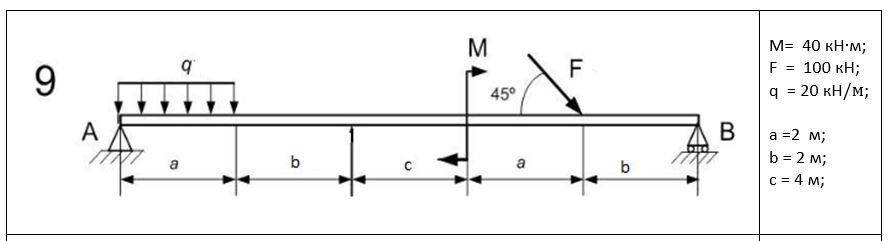

Система уравнений равновесия балки:


$$\begin{cases}
X_A + F * cos(45) = 0;
\\
Y_A + Y_B - F*sin(45) - Q = 0, Q = q * a;
\\
-Q * \frac{a}{2} -M -F*sin(45)*(2*a + b + c) + Y_B * (2a + 2b + c) = 0
\end{cases}$$


Перенесем все неизвестные в правую часть:


$$\begin{cases}
X_A = -F*cos(45);
\\
Y_A+Y_B = q*a + F*sin(45);
\\
Y_B*(2a + 2b +c)=q*\frac{a^2}2 + M + F*sin(45)*(2a+b+c)
\end{cases}$$


Приведем систему к матричному виду $A*X = B$ и решим ее:

syms a b c M F q A B;
A = [1 0 0; 0 1 1; 0 0 (2*a + 2*b + c)];
B = [-F * cosd(45); q*a + F*sind(45); q * a^2 * 0.5 + M + F*sind(45)*(2*a + b + c)];
X = linsolve(A, B);
a = 2;
b = 2;
c = 4;
M = 40;
F = 100;
q = 20;
xa = vpa(subs(X(1)));
ya = vpa(subs(X(2)));
yb = vpa(subs(X(3)));
Xa = X(1);
Ya = X(2);
Yb = X(3);
fprintf('Xa = %d, Ya = %d, Yb = %d\n', xa, ya, yb);

Xa = -71, Ya = 45, Yb = 66


Для проверки решения напишем сумму моментов относительно точки В и сумму сил:


$$\begin{cases}
M_B = -Y_A * (2a+2b+c)+F*sin(45)*b + q*a*(2b+c+1.5a) - M;
\\
\sum{F} = Y_B + Y_A - q*a - F*sin(45)
\end{cases}$$


MB = -Ya*(2*a + 2*b + c) + F*sind(45)*b + q*a*(2*b + c + 1.5*a) - M;
EF = Yb + Ya - q*a - F*sind(45);
subs(MB)

$$ans = 0$$

subs(EF)

$$ans = 0$$

Так как сумма моментов относительно точки B и сумма сил равны нулю, решение верное.

## 7.3 Графики.

Для построения графиков символьных функций, начиная с версии R2016a , в MATLAB  применяют команду fplot (раньше была ezplot).


$$f(x) = (1 - x + x^2)/(1+x-x^2), [0;1]
$$


**А.** Найти производную функции из табл.7.1 и построить для сравнения  два графика: 

- график функции *f**(**x**)*  и ее производной  в одних и тех же осях,  

- график зависимости между  *f**(**x**)*  и $f\prime \left(x\right)$, где значения функции откладываются по оси абсцисс, а производной – по оси ординат. Такой график называют «графиком в пространстве состояний» (SSP – state-space plot); x выступает в роли параметра.

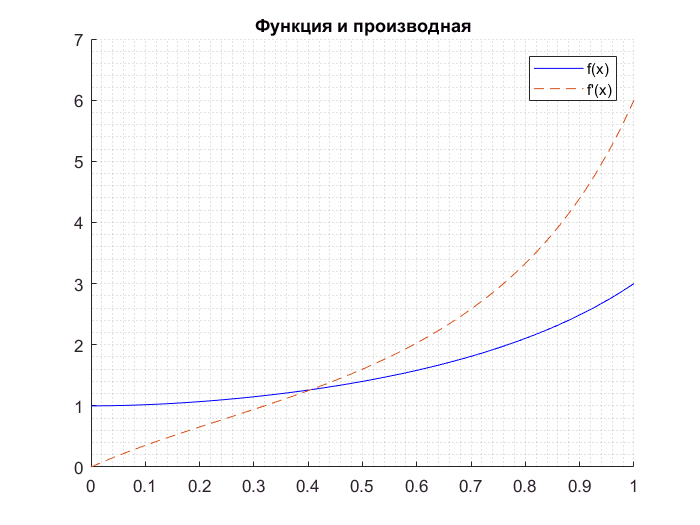

syms x;
f = (1 + x + x^2)/(1 + x - x^2);
figure('Name', 'Функция и производная', 'NumberTitle', 'off');
grid minor;
hold on;
fplot(f, [0 1], 'Color', 'blue');
fplot(diff(f), [0 1], '--');
axis([0 1 0 7]);
legend('f(x)', "f'(x)");
title('Функция и производная');

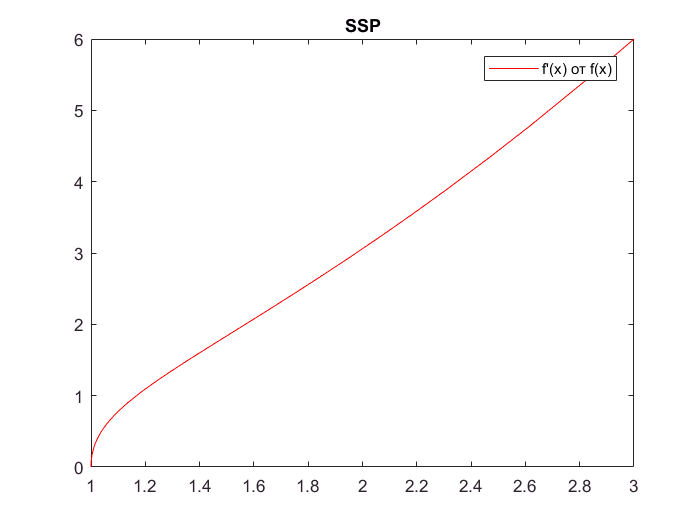

figure('Name', 'SSP', 'NumberTitle', 'off');
fplot(f, diff(f), [0 1],'Color', 'red');
legend("f'(x) от f(x)");
title('SSP');

**B.** Построить в интервале [-10,10]  графики двух пространственных кривых, заданных параметрически:

- $\begin{cases}
x(t) = cos(0.1t)*sin(10t)
\\
y(t) = 2*cos(10t)
\\
z(t) = 3t
\end{cases}$     синей  пунктирной линией, 

- $\begin{cases}
x(t) = cos(0.1*t)*sin(10t)
\\
y(t) = cos(0.1t)*cos(10t)
\\
z(t) = 3t
\end{cases}$ красной сплошной линией.

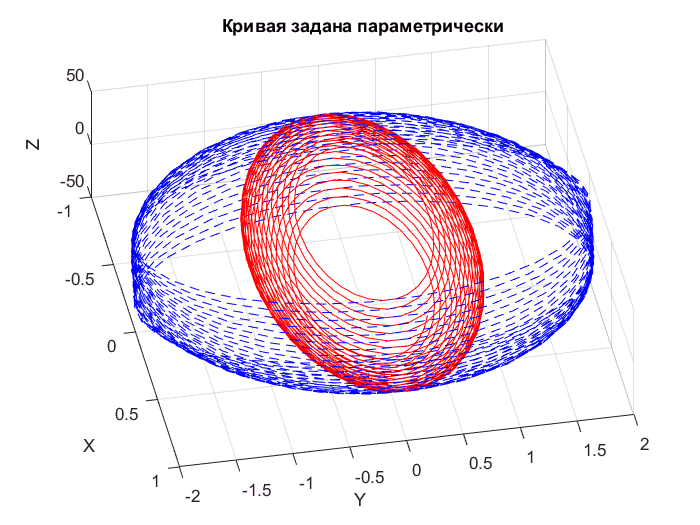

% --Вариант 1--
fx = @(t) cos(0.1.*t) .* sin(10.*t);
fy = @(t) 2 .* cos(10.*t);
fz = @(t) 3.*t;
figure;
hold on;
grid on;
fplot3(fx, fy, fz, [-10 10], '--', 'Color', 'blue');

% --Вариант 2--
fx = @(t) cos(0.1.*t) .* sin(10.*t);
fy = @(t) cos(0.1.*t) .* cos(10.*t);
fz = @(t) 3.*t;
fplot3(fx, fy, fz, [-10 10], 'Color', 'red');

title('Кривая задана параметрически');
xlabel('X');
ylabel('Y');
zlabel('Z');
view(79, 69);

## 7.4. Найти корни нелинейного уравнения

Задать переменную x и функцию f(x) символьными.  Для функции f(x) из таблицы,  найти корни нелинейного уравнения f(x)=0. 


$$f(x) = 4(1+x^{1/2})*ln(x) - 1$$


Преобразовать результат в десятичные числа, используя vpa(X,3) . Решить неравенство f(x)>0.   В обоих случаях использовать символьный решатель solve. Построить график fplot для символьной функции f(x) и график  area(z,f)  для такой же функции f(z) от  численной (double)  переменной z=-5:0.01:5 , чтобы наглядно убедиться в верном решении равенства и неравенства. *Желательно, чтобы символьные и численные переменные обозначались по-разному.*

syms x;
ff = @(z) 4*(1 + z.^0.5) .* log(z) - 1;
f = 4*(1 + x^0.5) * log(x) - 1;
fx = f == 0;
fy = f >= 0;
a = solve(fx, x)

$$a = 1.1288656117994576711265658228538$$

a = vpa(a, 3);
figure;
hold on;
grid on;
fplot(f, [-5 5], 'Color', 'red', 'LineWidth', 3);
%--Построение численной функции--
z = -5:0.01:5;
plot(z, ff(z), '-*', 'Color', 'green');

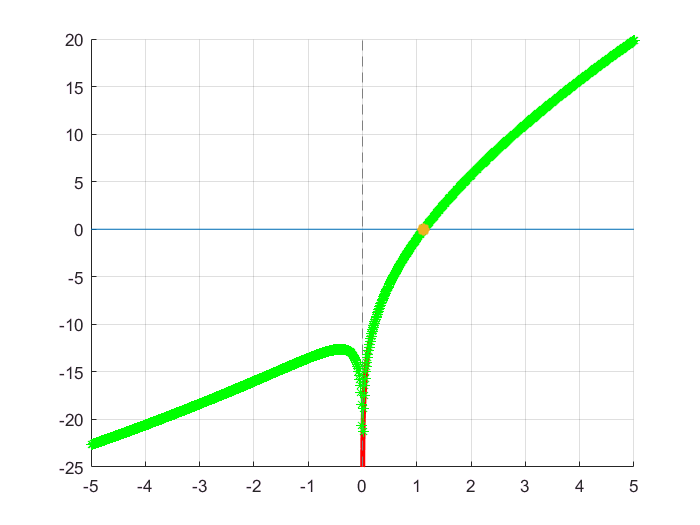

line([-5 5], [0 0]);
plot(a, 0, '*', 'LineWidth', 5);


% --MATLAB решать неравенство отказывается--
a = solve(fy, x, 'Real', true, 'IgnoreAnalyticConstraints', true);

## 7.5 Для символьной функции f(x) из предыдущего п.7.4 (табл.7.2)  вычислить неопределенный интеграл, а также определенный интеграл на интервале [1 2].

IN = int(f)

$$IN = 4\,x\,\left(\log\left(x\right)-1\right)-x+\frac{8\,x^{3/2}\,\left(\log\left(x\right)-\frac{2}{3}\right)}{3}$$

IO = int(f, [1 2])

$$IO = \log\left(256\right)+\frac{16\,\sqrt{2}\,\left(\log\left(2\right)-\frac{2}{3}\right)}{3}-\frac{29}{9}$$

## 7.6.         Построить графики кусочно-линейной  и кусочно-нелинейной  функций  с помощью команды `piecewise`.

А.   Значения параметра *a* задать самостоятельно:

             
$$y(x) = \begin{cases}
k(x+a), x < -a
\\
0, -a \leq x \leq a
\\
k(x - a), a < x
\end{cases}$$


Ввод значения    предусмотреть с клавиатуры: 

       `prompt = ``'Enter the value of the variable'``;`

       `x`` = ``input``(``prompt``)`           

Желательно выводить изображение основного графика и его соответствующей его части на одном  рисунке с помощью команды `subplot`. В случае, когда переменная не попадает в заданный диапазон,  выводить предупреждение: 

`disp(``' Warning: the value is out of range '``)` 

syms y(x);
k = 5;
a = 3;
xx = input('Ввесдите х: ');
y(x) = piecewise(x < -a, k*(x + a), -a <= x <= a, 0, a < x, k*(x - a))

$$y(x) = \left\{ \begin{array}{cl} 5\,x+15 & \text{ if }x<-3\\ 0 & \text{ if }x\in \left[-3,3\right]\\ 5\,x-15 & \text{ if }3<x \end{array}\right.$$

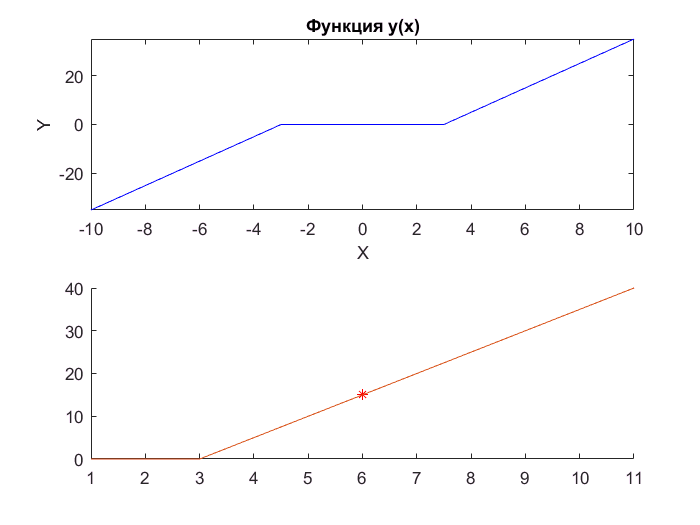

figure;
subplot(2, 1, 1);
fplot(y(x), [-10 10], 'Color', 'blue');
title('Функция y(x)');
xlabel('X');
ylabel('Y');
subplot(2, 1, 2);
hold on;
l = vpa(subs(y(xx)), 3);
plot(xx, l, '*', 'Color', 'red');
fplot(y(x), [xx-5 xx+5]);

fprintf("Значение функции f в точке %f %f \n", xx, l);

Значение функции f в точке 6.000000 15.000000 


В.   Построить ***график кусочно-НЕлинейной функции,*** заданной выражением 

 
$$x(t) = \begin{cases}
exp(t), -3 < t \leq 0;
\\
cos(t - \frac{\pi}2), 0 < t \leq \pi;
\\
exp(t - \pi), \pi <t < 4.24.
\end{cases}$$


Предусмотреть ввод значения    с клавиатуры 

       `prompt = ``'Enter the value of the variable'``;`

       `t`` = ``input``(``prompt``)`

Желательно выводить рядом на одном рисунке  основной график и изображение той части графика, в диапазон  которой попадает t.  Использовать команду `subplot`.  

Значение функции f в точке 2.000000 0.909297 


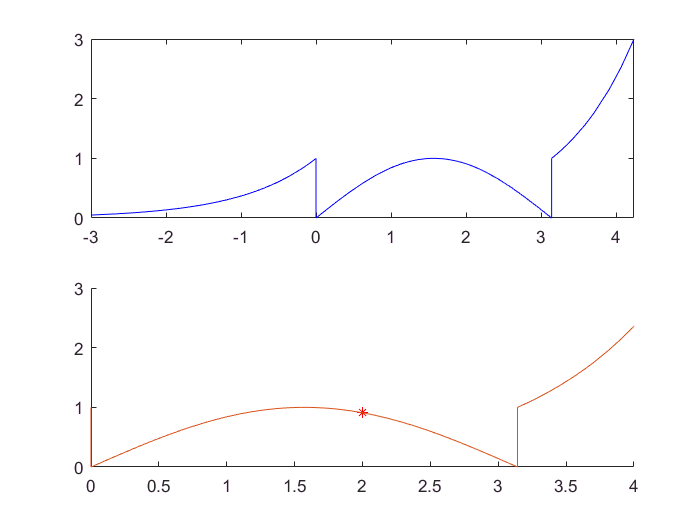

syms x(t);
x(t) = piecewise(-3 < t <= 0, exp(t), 0 < t <= pi, cos(t - pi/2), pi < t < 4.24, exp(t - pi));
tt = input('Введите значение переменной с клавиатуры: ');
if(tt < -3 || tt > 4.24)
    disp('Ошибка! Переменная лежит вне области построения функции!');
else
    figure;
    subplot(2, 1, 1);
    fplot(x(t), [-3 4.24], 'Color', 'blue');
    subplot(2, 1, 2);
    hold on;
    l = vpa(subs(x(tt)), 3);
    plot(tt, l, '*', 'Color', 'red');
    fplot(x(t), [tt-2 tt+2]);
    fprintf("Значение функции f в точке %f %f \n", tt, l);
end

С.  Запрограммировать и вывести периодическую функцию, имитирующую изменение температуры в термостате при срабатывании специального термореле (темно-зеленая линия на рис. 7.1). Построить аналогичный график на интервале [0 20].

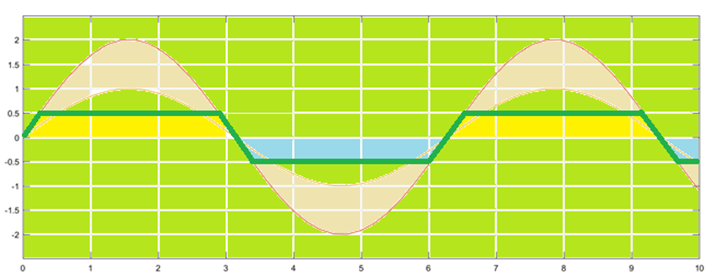

**Рис.7.1. **Изменение температуры в термостате при срабатывании специального термореле

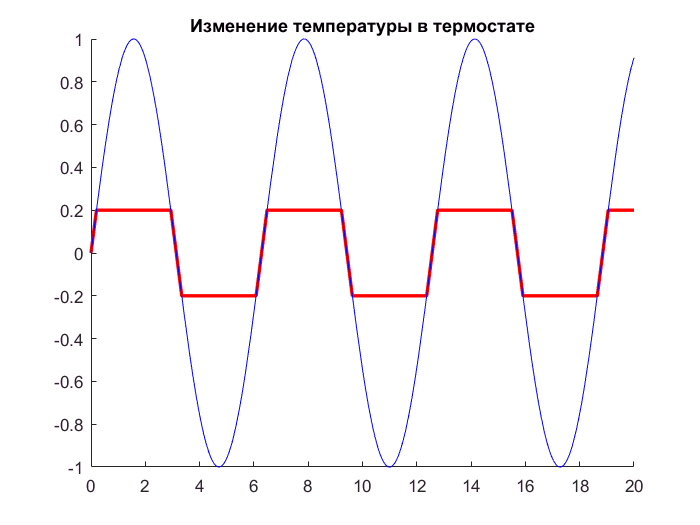

syms y(x);
y(x) = piecewise(sin(x) >= 0.2, 0.2, sin(x) <= -0.2, -0.2, cos(x) < 0, sin(x), cos(x) >= 0, sin(x));
figure;
hold on;
fplot(y(x), [0 20], 'Color', 'red', 'LineWidth', 2);
fplot(sin(x), [0 20], 'Color', 'blue');
title('Изменение температуры в термостате');

## 7.7.       Найти минимум или максимум функции (табл.7.3), полагая ее символьной. 

 Использовать   для поиска minimum условие равенства нулю первой символьной производной функции  и проверку положительного знака у её второй символьной производной.


$$0.2*x + sin(2x) \rightarrow max, [0; 3], \Delta = 0.02$$


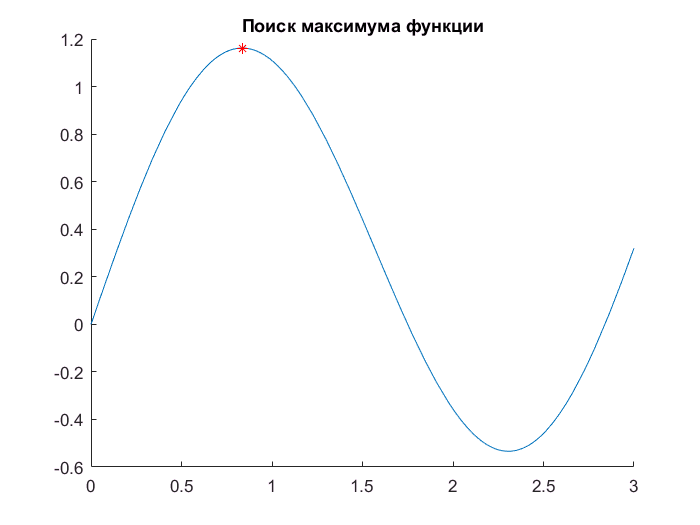

syms f(x);
f(x) = 0.2*x + sin(2*x);
sol = solve(diff(f(x)) == 0, x);
figure;
hold on;
fplot(f(x), [0 3]);
ddf(x) = diff(f(x), 2);
if(ddf(sol(1)) < 0)
    fplot(vpa(sol(1), 3), f(sol(1)), '*', 'Color', 'red');
else
    fplot(vpa(sol(2), 3), f(sol(2)), '*', 'Color', 'red');
end;
title('Поиск максимума функции');

## 7.8.  Разложить функцию из предыдущего п.7.7  (табл.7.3) в ряд Тейлора на концах заданного интервала. 

Задать во входных  аргументах функции taylor разный  порядок усечения ряда 'Oder' : 4,5, (6 по умолчанию). Построить, используя fplot,  два графика для двух разных точек разложения.  На каждом показать функцию красной сплошной линией толщины 1.5, а  3 ее разложения – прерывистыми линиями (черной, синей, зеленой).  Каждый график озаглавить   «Функция  *f(x)=…* и ee разложения в ряд Тейлора в точке  *a *=… » . 

Проверить полученный вид разложения, открыв  графический  интерфейс Taylor Series Calculator с помощью команды 

                  `taylortool``(``'<``f``(``x``)>'``)`

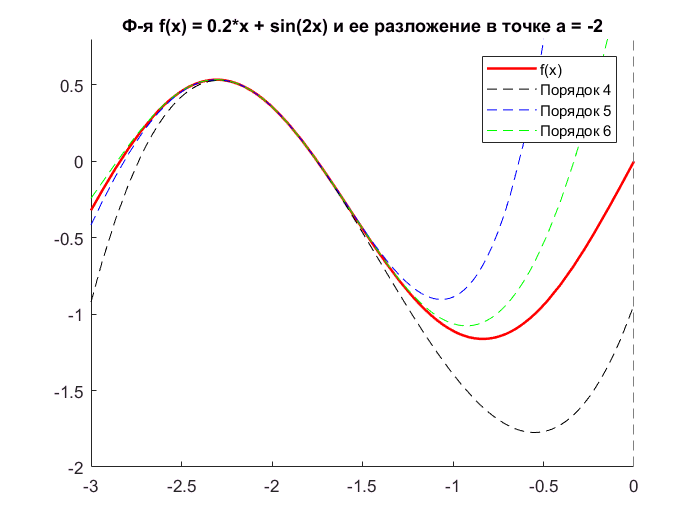

syms f(x);
f(x) = 0.2*x + sin(2*x);
figure;
hold on;
fplot(f(x), [-10 10], 'Color', 'red', 'LineWidth', 1.5);
fplot(taylor(f(x), x, -2, 'Order', 4), [-10 10], '--', 'Color', 'black');
fplot(taylor(f(x), x, -2, 'Order', 5), [-10 10], '--', 'Color', 'blue');
fplot(taylor(f(x), x, -2, 'Order', 6), [-10 10], '--', 'Color', 'green');
title('Ф-я f(x) = 0.2*x + sin(2x) и ее разложение в точке a = -2');
axis([-3 0 -2 0.8]);
legend('f(x)', 'Порядок 4', 'Порядок 5', 'Порядок 6');

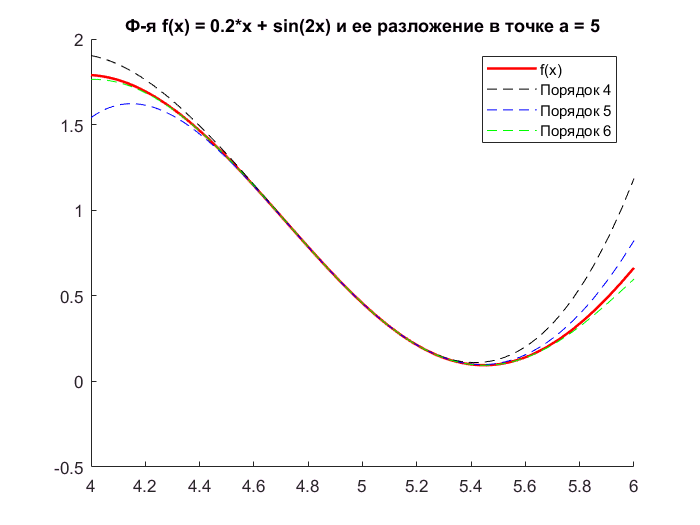


figure;
hold on;
fplot(f(x), [-10 10], 'Color', 'red', 'LineWidth', 1.5);
fplot(taylor(f(x), x, 5, 'Order', 4), [-10 10], '--', 'Color', 'black');
fplot(taylor(f(x), x, 5, 'Order', 5), [-10 10], '--', 'Color', 'blue');
fplot(taylor(f(x), x, 5, 'Order', 6), [-10 10], '--', 'Color', 'green');
title('Ф-я f(x) = 0.2*x + sin(2x) и ее разложение в точке a = 5');
axis([4 6 -0.5 2]);
legend('f(x)', 'Порядок 4', 'Порядок 5', 'Порядок 6');

## 7.9 Определить, при каких значениях k будет положительным детерминант символьной матрицы?

                      M = [1 k 3;  2 4 2*k;  4 -2 k] 

syms k;
M = [1 k 3; 2 4 2*k; 4 -2 k];
Z = sym(M);
f = det(M)

$$f = 6\,k^{2}+8\,k-60$$

sol = solve(f == 0, k)

$$sol = \left(\begin{array}{c} -\frac{\sqrt{94}}{3}-\frac{2}{3}\\ \frac{\sqrt{94}}{3}-\frac{2}{3} \end{array}\right)$$

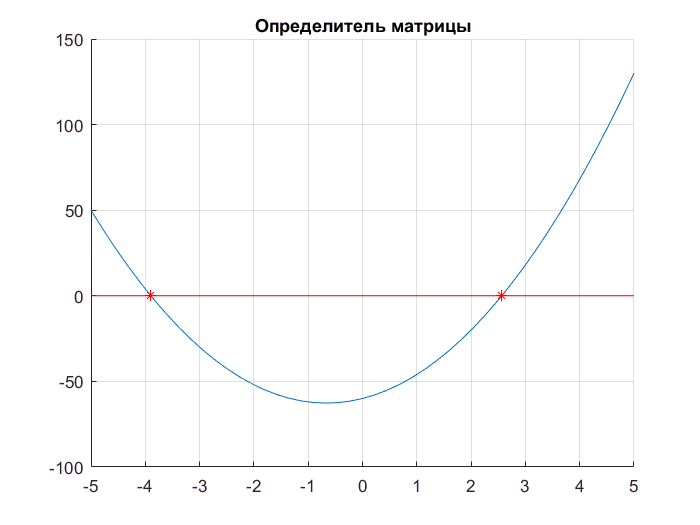

figure;
hold on;
grid on;
fplot(f);
line([-5 5], [0 0], 'Color', 'red');
plot(vpa(sol(1)), 0, '*', 'Color', 'red');
plot(vpa(sol(2)), 0, '*', 'Color', 'red');
title('Определитель матрицы');